# Computational Physics Assignment 2

#### Nilkamal Thakuria, 2018B5A70924P

## Important notes for executing the live script

- Please click on the **hide code option** in the **view tab** to view the file with only text, outputs and graphs.

- Some parameters can be changed with sliders. The sliders will still be visible on hiding the code.

- I have also attached the code as regular .m files for each question, if in some case the live script fails.

clc;
clear;
close all;
clear livescript;

## Q1) Part a)


$$F\left(k,\phi \right)=\int_0^{\phi } \left(\frac{1}{\sqrt{1-k^2 \sin^2 \phi^{\prime } }}\right)d\phi^{\prime }$$


Using Simpson's 1/3rd rule the integration can be solved numerically. However, the function to be integrated may approach infinity at some points within the specified interval, so a careful selection of both $k$ and $\phi$ is necessary to ensure correctness.

% Question 1a %
clc;
clear;
close all;
clear livescript;
k=1;
b=1.57;
a=0; 
f=@(theta) (1/sqrt(1-(k^2)*(sin(theta))^2));
% Dividing the interval (a,b) into 10001 points, with step size h
N=10001; h=(b-a)/(N-1);
x=linspace(a,b,N);
I=0;
for i=1:2:N-2
    I=I+(h/3)*(f(x(i))+4*f(x(i+1))+f(x(i+2)));
end
disp("Integral value using Simpson's rule is: "+I);

Integral value using Simpson's rule is: 7.8287


## Q1) Part b)

To find: Time period of the equation below:


$$\theta^{\ldotp \ldotp } =-\omega^2 \sin \left(\theta \right)$$


Using RK4 method for two equations we obtain the angular position and velocity at different time stamps.

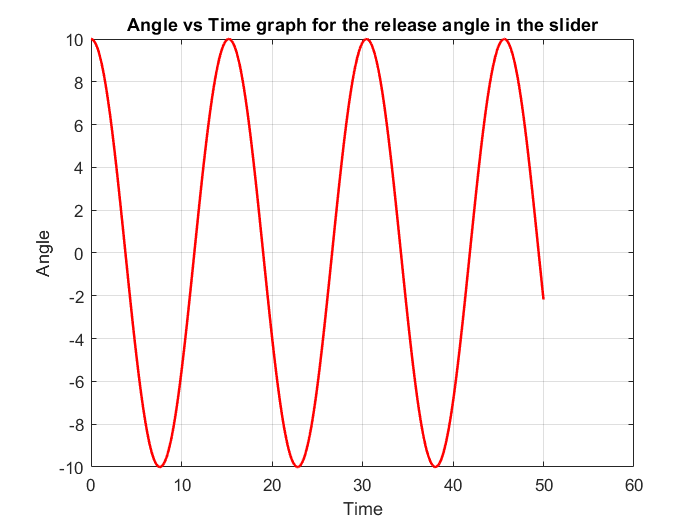

% y1, y2 are the angular position and velocity
% f1, f2 are their respective time derivatives
L=1;
g=9.8;

w0=sqrt(g/L);
y10=10;
y20=0;
f1=@(t,y1,y2) y2;
f2=@(t,y1,y2) (-(w0^2)*(sind(y1)));

startTime=0;
endTime=50;

[x,y1,y2,tP]=RK4_2equations(1000,startTime,endTime,y10,y20,f1,f2,0);

plot(x,y1,'r', 'LineWidth',1.5);
grid on;
title('Angle vs Time graph for the release angle in the slider');
xlabel('Time');
ylabel('Angle');

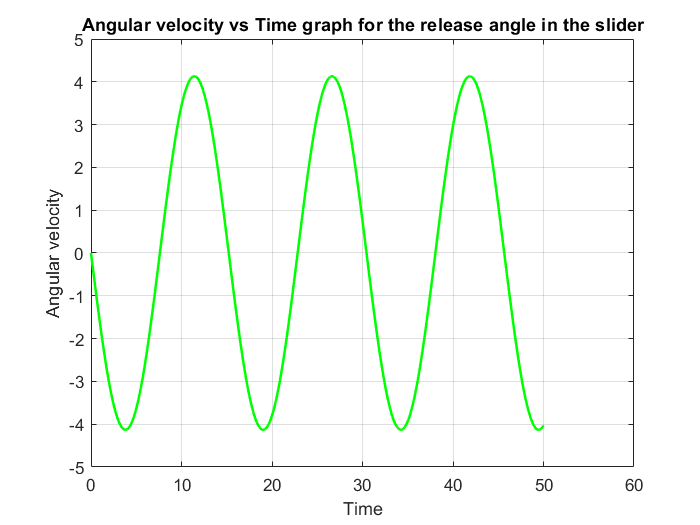



plot(x,y2,'g', 'LineWidth',1.5);
grid on;
title('Angular velocity vs Time graph for the release angle in the slider');
xlabel('Time');
ylabel('Angular velocity');

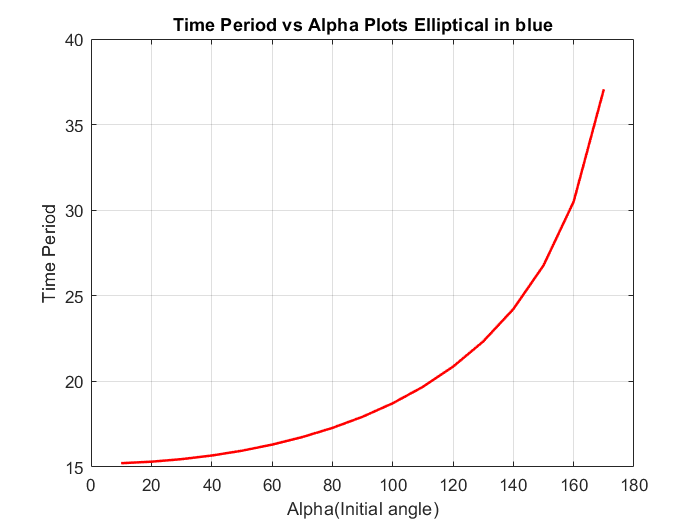



% % Calculating Time period for different alphas
timePeriods=zeros(1,17);
k=1;
for i=10:10:170
    [~,~,~,tP]=RK4_2equations(1000,0,30,i,0,f1,f2,1);
    timePeriods(k)=tP;
    k=k+1;
end
alphas=linspace(10,170,17);
plot(alphas,timePeriods,'r', 'LineWidth',1.5);
grid on;
title('Time Period vs Alpha Plots Elliptical in blue');
xlabel('Alpha(Initial angle)');
ylabel('Time Period');

### Q1 Part c)

Elliptical Integral formula:


$$T=4\sqrt{\frac{l}{g}}F\left(k,\frac{\pi }{2}\right)$$


We find out the time period given by the above formula and plot it against our calculated values in part b. The blue line represents the time periods calculated using the above formula, and the red line using the results from part b.

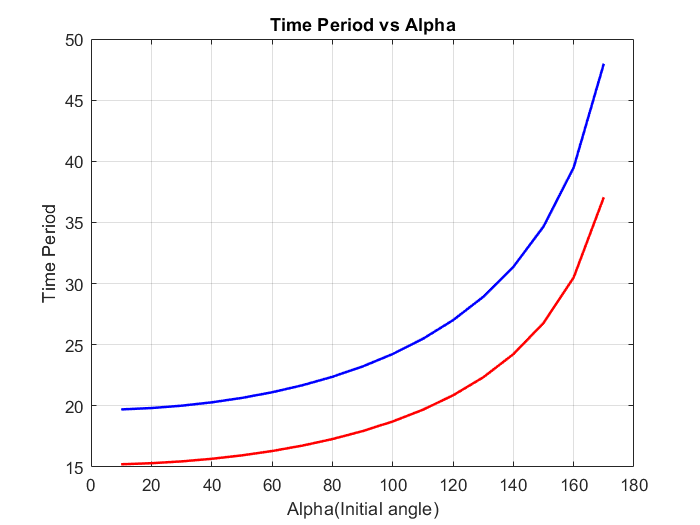

% Integral calculated for various angles
theoryTimePeriods = zeros(1,17);
for i=1:17
    k=sind(i*5);
    b=pi/2;
    a=0;  
f=@(theta) (1/sqrt(1-(k^2)*(sin(theta))^2));
% Dividing the interval (a,b) into 10001 points, with step size h
    N=10001; h=(b-a)/(N-1);
    x=linspace(a,b,N);
    I=0;
    for j=1:2:N-2
        I=I+(h/3)*(f(x(j))+4*f(x(j+1))+f(x(j+2)));
    end
    theoryTimePeriods(i) = 4*w0*I;
end


plot(alphas,theoryTimePeriods,'b', 'LineWidth',1.5);
grid on;
title('Time Period vs Alpha');
xlabel('Alpha(Initial angle)');
ylabel('Time Period');
hold on
plot(alphas,timePeriods,'r', 'LineWidth',1.5);
hold off

% % ***********

### Q3)

Differential equation for catenary curve(hanging chain)


$$\frac{d^2 }{\mathrm{d}x^2 }y=a\sqrt{1+\frac{\mathrm{d}}{\mathrm{d}x}y}$$


% Let y1=y and y2=dy/dx
% Then f1=y2 and f2=a*sqrt(1+y2), (derivatives of y1 and y2 wrt x)
% y1(0)=0, y1(10)=0;
% Length of chain=10n (n=2,3,4,5)
clc;
clear;
close all;
clear livescript;

% Assigning arbitrary value to a;
a=0.43;

% The values of a for the given lengths are(calculated after manually tweaking a):
% L=20, a=0.435463;
% L=30, a=0.567689;
% L=40, a=0.652759;
% L=50, a=0.715647;



f1=@(x,y1,y2) y2;
f2=@(x,y1,y2) a*sqrt(1+(y2)^2);

% Range of x
left=0; right=10;
y_left=0; y_right=0;

% Shooting method
alpha=(y_right-y_left)/(right-left);
epsilon=0.0001;
N=10000;
[x,y1,y2]=RK4_2equationsB(N,left,right,y_left,alpha,f1,f2);

count=1;
while (abs(y1(N)-y_right)>epsilon)
    alpha=alpha+(y_right-y1(N))/(right-left);
    [x,y1,y2]=RK4_2equationsB(N,left,right,y_left,alpha,f1,f2);
    count=count+1;
    if(count==10000)
        break;
    end
end

% Calculating length of chain
LengthOfChain=0;
for i=2:N
    LengthOfChain = LengthOfChain + sqrt((y1(i)-y1(i-1))^2 + (x(i)-x(i-1))^2);
end

disp("Length of chain for given value of a in slider is: "+LengthOfChain);

Length of chain for given value of a in slider is: 19.6939


For getting the specific length of 10n(n=2,3,4,5), the program is repeatedly executed for different values of a, and the value of a is tweaked until it hits the specified length.

% Thus, the values of a are:
disp("Values of a for the following lengths are: ")

Values of a for the following lengths are: 


disp("L=20, a=0.435463");

L=20, a=0.435463


disp("L=30, a=0.567689");

L=30, a=0.567689


disp("L=40, a=0.652759");

L=40, a=0.652759


disp("L=50, a=0.715647");

L=50, a=0.715647


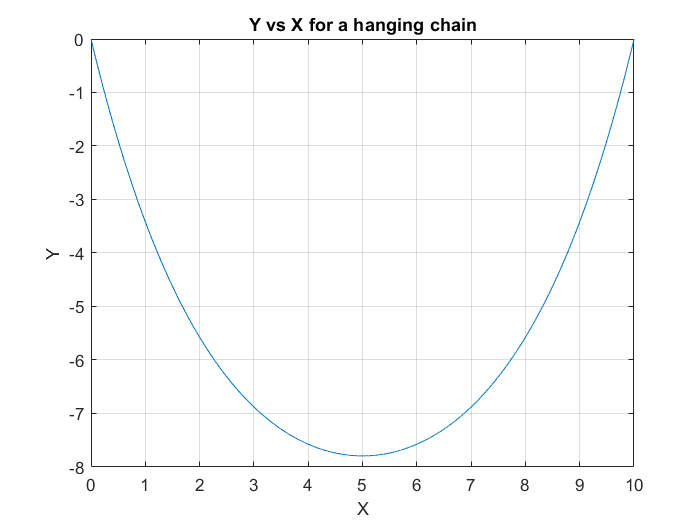


plot(x, y1);
grid on
title("Y vs X for a hanging chain");
xlabel('X');
ylabel('Y');

### Q5) Boiling potato

Heat equation in 3 dimensions for a spherical body is given by:


$$\frac{\partial }{\partial t}u=\alpha^2 \left(\frac{\partial^2 }{\partial r^2 }u+\frac{2}{r}\frac{\partial }{\partial r}u\right),{\;\textrm{where}\;\alpha }^2 =\frac{k}{c\rho }$$


We discretise temperature as a function of* m(distance from center)* and *n(time).* Using forward difference scheme for the time derivative, and central difference scheme for the first and second derivatives with respect to r, we get the following relation:


$$u\left(m,n+1\right)=\left(1-2r\right)u\left(m,n\right)+\frac{r\left(m*u\left(m+1,n\right)+\left(m-2\right)*u\left(m-1,n\right)\right)}{m-1};\textrm{where}\;r=$$

$$\alpha^2 k/h^2$$


We use Dirichlet boundary conditions, and initial conditions as given in the question.

clc;
clear;
close all;
clear livescript;

% Time into steps of 0.05 seconds
k=0.05;

% Potato specifications
K=0.8;
R=0.04;
rho=1070;
c=3390;
a=K/(c*rho);


% Distance from center discretized into 101 points
M=101; N=40001;
h=R/(M-1);
r=a*k/(h^2);
u=zeros(M,N);
x = 0:h:R;


T_boil=100;
% On just dipping the potato in boiling water, the insides will be at 25C while
% boundary is at 100C
u(1:M-1,1)=25;u(M,1)=T_boil;

% Waiting till the center reaches 70C
n=1;
while u(1,n) < 70    
    for m = 2:M-1
        u(m,n+1) = (1-2*r)*u(m,n) + r*((m-2)*u(m-1,n)+m*u(m+1,n))/(m-1);
    end
    % From dirichlet boundary conditions
    u(1,n+1) = u(2,n+1);
    u(M,n+1) = T_boil;
    n=n+1;
end
T_warm =(n-1)*k/60;
disp("Time required for heating the potato in minutes is: "+T_warm);

Time required for heating the potato in minutes is: 19.6142



T_room=25;
n_next=n+1;
u(1:M-1,n_next)=u(1:M-1,n);
u(M,n_next)=T_room;

while (u(1,n_next)>=(T_room + 5))
    for m = 2:M-1
        u(m,n_next+1) = (1-2*r)*u(m,n_next) + r*((m-2)*u(m-1,n_next)+m*u(m+1,n_next))/(m-1);
    end
    % From dirichlet boundary conditions
    u(1,n_next+1) = u(2,n_next+1);
    u(M,n_next+1) = T_room;

    n_next = n_next +1;
end
T_cool = k*(n_next-n-1)/60;
disp("Time required for cooling the potato in minutes is: "+T_cool);

Time required for cooling the potato in minutes is: 38.9058


The heating phase has a curve as expected, temperature at the center gradually increases to 70C, while the boundary remains at 100C. We then put the potato out of the boiling water, and place it in room temperature. However, the temperature at the center still keeps increasing upto a certain point(around 79.1C) because of heat flow inwards in the potato, as the points away from the center are at a higher temperature. The center point then starts cooling down once the surrounding points are at a lower temperature than itself.

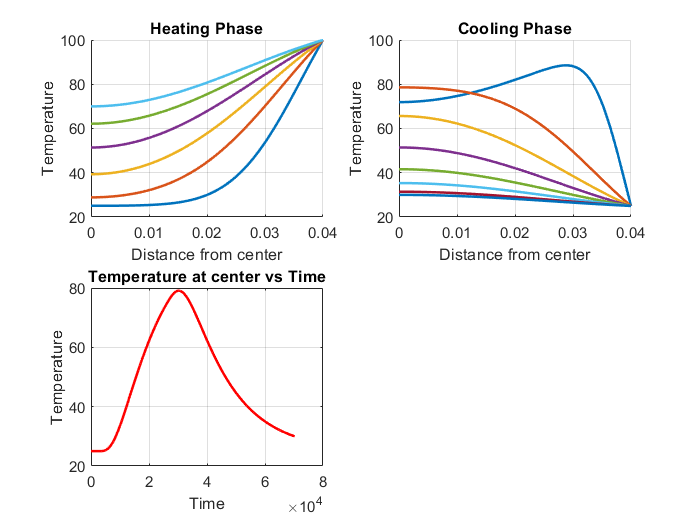

subplot(2,2,1)
hold on
for i=4001:4000:n
plot(x,u(:,i),'linewidth',1.5)
end
plot(x,u(:,n),'linewidth',1.5)
title('Heating Phase')
xlabel('Distance from center')
ylabel('Temperature')
grid on
hold off

subplot(2,2,2)
hold on
for i=n+1000:7000:n_next
plot(x,u(:,i),'linewidth',1.5)
end
plot(x,u(:,n_next),'linewidth',1.5)
title('Cooling Phase')
xlabel('Distance from center')
ylabel('Temperature')
grid on
hold off

subplot(2,2,3)
plot(u(1,:),'r','linewidth',1.5)
title('Temperature at center vs Time')
xlabel('Time')
ylabel('Temperature')
grid on

### Q6)

The graphs below display the propagation of a wavepulse at different time instances, starting from rest at the center of a string with given parameters. The wave equation:


$$\frac{\partial^2 }{\partial t^2 }u=v^2 \frac{\partial^2 }{\partial x^2 }u$$


is first discretized as ***u(m,n), m={1,2,3...M} and n={1,2,3,...N}, m is discretized distance, n is discretized*** ***time.*** ***The step size for m and n is h and k respectively***. the central difference scheme is applied for both of the second derivatives. Thus, we get the following equation:


$${u\left(m,n+1\right)=a}^2 \left(u\left(m+1,n\right)+u\left(m-1,n\right)\right)+2\left(1-a^2 \right)u\left(m,n\right)-u\left(m,n-1\right);\textrm{where}\;a=\frac{c*k}{h}$$


The two initial conditions will be given by the initial displacement profile, which in this case is a gaussian wavepulse at the center of the string, and the initial velocity profile, in this case it's stationary. Hence *u(m,2)=u(m,1).*

Also, we use the two Newmann boundary conditions(rings at both ends). This implies


$$\frac{\partial }{\partial x}u=0;\;\textrm{at}\;x=\left\lbrace 0,L\right\rbrace$$


Thus, using ghost boundary points and the aforementioned conditions, we get the following relations:


$$u\left(1,n+1\right)=2a^2 u\left(2,n\right)+2\left(1-a^2 \right)u\left(1,n\right)-u\left(1,n-1\right)$$



$$u\left(M,n+1\right)=2a^2 u\left(M-1,n\right)+2\left(1-a^2 \right)u\left(M,n\right)-u\left(M,n-1\right)$$


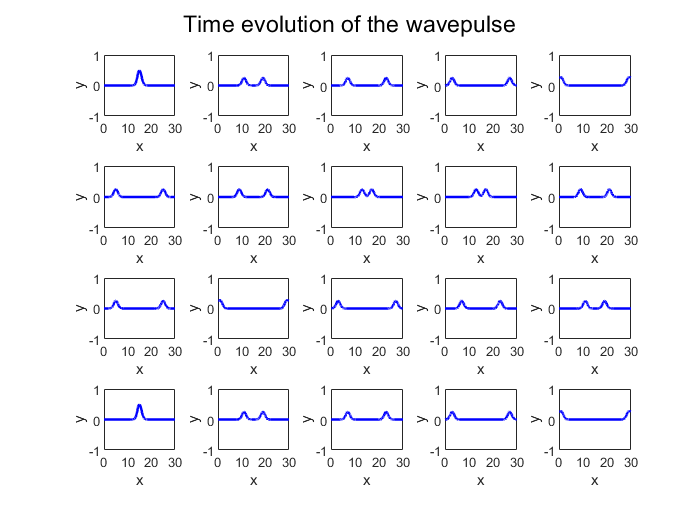

clc;
clear;
close all;
clear livescript;

T=0.1; mu=0.1;
c=sqrt(T/mu);
L=30;h=0.01;
M=L/h+1;
x=linspace(0,L,M);
k=0.01;
a=c*k/h;

u(1,:)=0; u(M,:)=0;
n1=fix(M/2)+1;alpha=600;

for n=1:M
    u(n,1)=0.5*exp(-alpha*((x(n)-x(n1))^2)/L^2);
    u(n,2)=0*(2*alpha*k*c/L^2)*(x(n)-x(n1))*u(n,1)+u(n,1);
end



T=zeros(1,20); N=zeros(1,20);
for i=1:20
    T(i)=4*(i-1);
    N(i)=T(i)/k+1;
    u(1,:)=0; u(M, :)=0;
    
    for n=2:N(i)
        u(1,n+1)=2*a^2*u(2,n)+2*(1-a^2)*u(1,n)-u(1,n-1);
        for m=2:M-1
            u(m,n+1)=a^2*(u(m+1,n)+u(m-1,n))+2*(1-a^2)*u(m,n)-u(m,n-1);
        end
        u(M,n+1)=2*a^2*u(M-1,n)+2*(1-a^2)*u(M,n)-u(M,n-1);
        
    end
    
    subplot(4,5,i);
    plot(x, u(:,N(i)),'blue', 'linewidth', 1.5);
    xlabel("x");
    ylabel("y");
    axis([0 L -1 1]);
end
sgtitle('Time evolution of the wavepulse');

This section contains the RK_4 method code. Press output on right button to view it.

function[x,y1,y2]=RK4_2equationsB(N,x0,xn,y10,y20,f1,f2)
% Basic RK_4
h=(xn-x0)/(N-1);
x=zeros(1,N); y1=zeros(1,N); y2=zeros(1,N);
x(1)=x0; y1(1)=y10; y2(1)=y20;

for i=2:N
    k11=f1(x(i-1), y1(i-1), y2(i-1));
    k21=f2(x(i-1), y1(i-1), y2(i-1));
   
    k12=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    k22=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    
    k13=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    k23=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    
    k14=f1(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    k24=f2(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    
    y1(i)=y1(i-1)+h*(k11+2*k12+2*k13+k14)/6;
    y2(i)=y2(i-1)+h*(k21+2*k22+2*k23+k24)/6;
   
    x(i)=x(i-1)+h;
end


% RK_4 method, customised for question 1
end
function[x,y1,y2,tP]=RK4_2equations(N,x0,xn,y10,y20,f1,f2,timePeriodFindEnable)
tP=0;

if(timePeriodFindEnable==0)
h=(xn-x0)/(N-1);
x=zeros(1,N); y1=zeros(1,N); y2=zeros(1,N);
x(1)=x0; y1(1)=y10; y2(1)=y20; 
    
    
for i=2:N
    k11=f1(x(i-1), y1(i-1), y2(i-1));
    k21=f2(x(i-1), y1(i-1), y2(i-1));
   
    k12=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    k22=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    
    k13=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    k23=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    
    k14=f1(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    k24=f2(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    
    y1(i)=y1(i-1)+h*(k11+2*k12+2*k13+k14)/6;
    y2(i)=y2(i-1)+h*(k21+2*k22+2*k23+k24)/6;
   
    x(i)=x(i-1)+h;
end

else
    N=100000;
    h=(xn-x0)/(N-1);
    x=zeros(1,N); y1=zeros(1,N); y2=zeros(1,N);
    x(1)=x0; y1(1)=y10; y2(1)=y20; 
    
for i=2:N
    
    y2_prev=y2(i-1);
    
    k11=f1(x(i-1), y1(i-1), y2(i-1));
    k21=f2(x(i-1), y1(i-1), y2(i-1));
   
    k12=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    k22=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k11, y2(i-1)+(h/2)*k21);
    
    k13=f1(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    k23=f2(x(i-1)+h/2, y1(i-1)+(h/2)*k12, y2(i-1)+(h/2)*k22);
    
    k14=f1(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    k24=f2(x(i-1)+h, y1(i-1)+(h)*k13, y2(i-1)+(h)*k23);
    
    y1(i)=y1(i-1)+h*(k11+2*k12+2*k13+k14)/6;
    y2(i)=y2(i-1)+h*(k21+2*k22+2*k23+k24)/6;
   
    x(i)=x(i-1)+h;
    
    if((y2(i)*y2_prev)<0)
        break;
    end
end
    tP=2*i*h;
end
end